# A Discrete Cell Division Model - Part I

**During this assignment, you will pracitice the following: **

**Mathematical skills:** substitution, equations, equality, abstraction, disceret modeling

**Coding skills**: for loops, plots, vectors, assigning values, indexing

**Tasks **

**Step 1: Go through this example. Feel free to play with the code and see what happens! **

**Step 2: Answer the questions at the 'Questions 1' section at the bottom of this guide in a group **

Note: this guide includes explanation behind the math used for the code. You are*** not*** expected to reproduce this math. But if you were curious, you can refer to the guide to learn more about the math that we use in our models.

## Intro 

One model to explain cell population uses *discrete steps* and the concept of *daughter* cells. At each step, the cells simultaneously divide into $b$ daughter cells. Here, we explore what happens when we play around with the value of $b$.

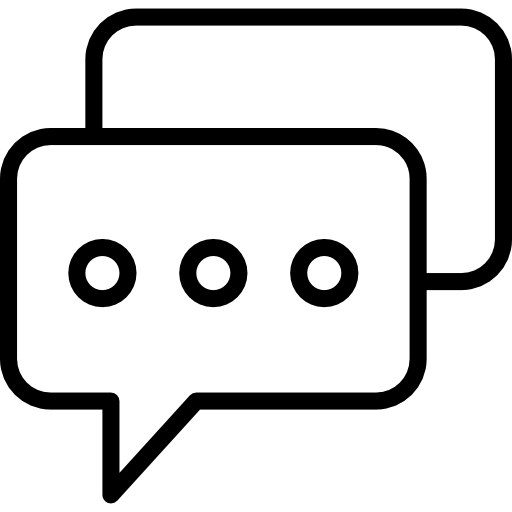 **Group Chat:** If we know the number of cells at a generation, how do we calculate the number of cells immediately after division?

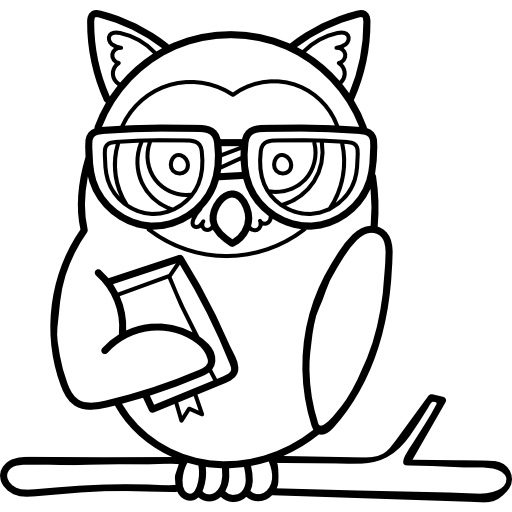  **Owl Tip:** If we start with 1 cell that divides in 2, we will have 2 cells after the division. If we start with 1 cell that divides into 3, we will have 3 cells after the division! Now if we start with 2 cell that divide into 2 each, we will have...

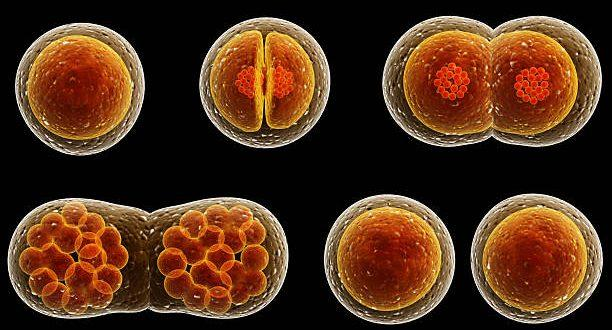

source: *https://mysciencesquad.weebly.com/16-cell-division.html*

## Code

  **Owl Tip:** You can edit the blank fields to answer the questions at the end of this program!

First, assign the number of initial cells M0, 

M0 = 1;

Choose the number of generations `n` 

n = 4;

and the number of daughter cells `b` at each step:

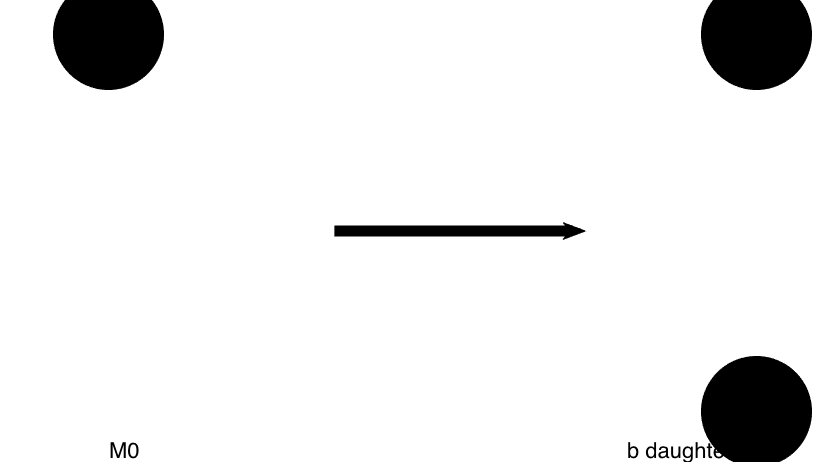

b = 2;

Schematic(M0,b,100)

We create `M`, a place-holder vector that keeps a history of the cell population.

M = ones(1,n);

We also create a vector, `Generation`, that counts up to the generation of our interest:

Generation = linspace(0,n,n+1);

By multiplying the population number at each generation with `b, `the number of cells that each cell divides into, we can calculate the population number right after the division! 

$M_1 =b\times M_0$.

M(1) = M0*b;
M(1)

ans = 2

Using a *for loop *we repeat this starting with the initial population and up the generation that we are interested in. To get the population number at the $k+1$th generation, we multiply the population number at $k$th generation by $b$:

$M_{k+1} =b\times M_k$.

Use a loop to create cells at each step

for k = 1:1:n-1
    M(k+1) = b*M(k); % at each step, we multiply the number of cells by b!
end

## Graphs

Visualization of data usually helps us better understand it. Here, we graph the population number at each generation as a function of the generation:

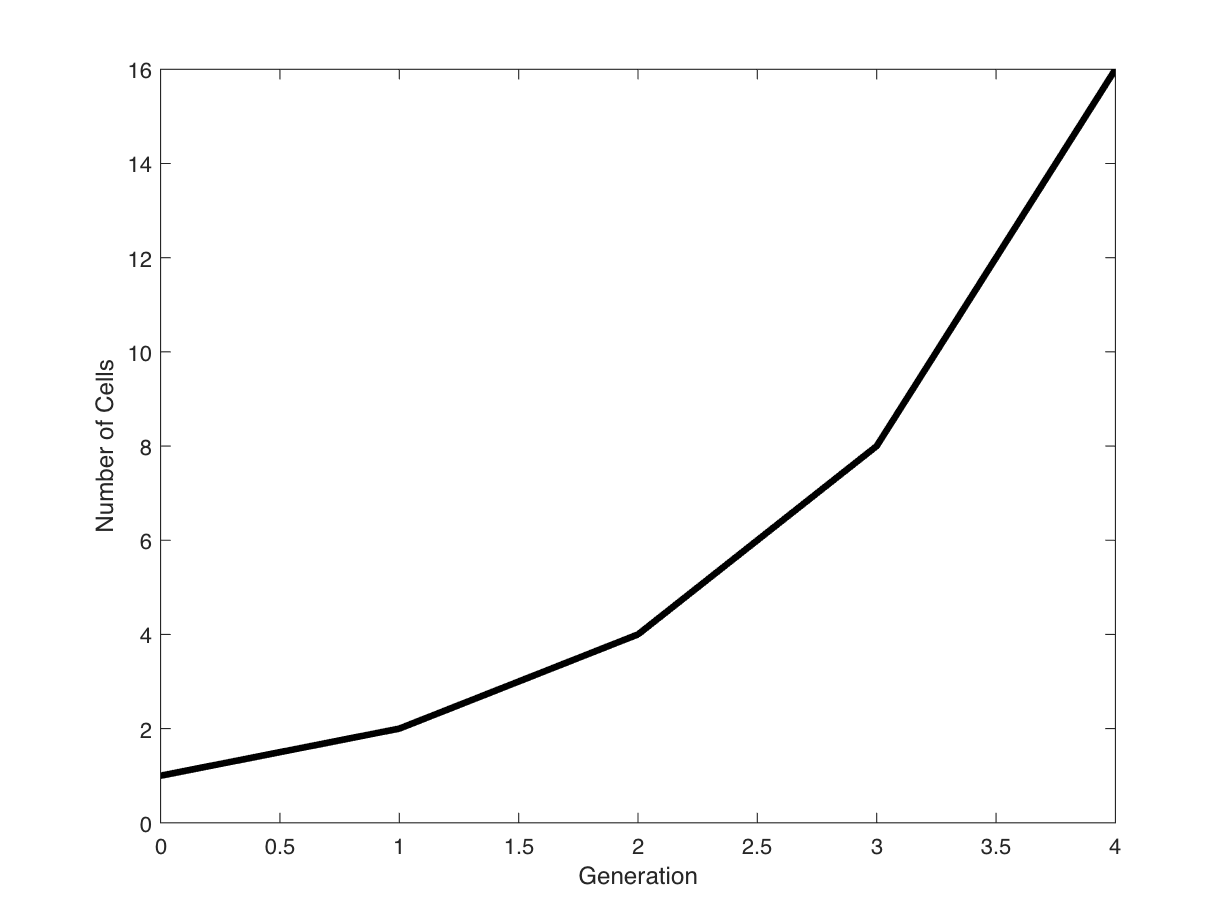

figure(2)
plot(Generation,[M0 M], 'LineWidth', 3, 'Color','k')
xlabel('Generation')
ylabel('Number of Cells')

Here, we were interested in the population number at the final generation. Let's display it here:

M(end) 

ans = 16

## Questions Part 1

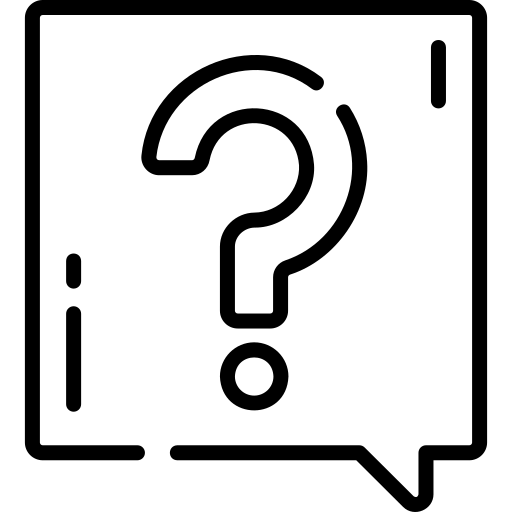 Can you, in your own words, describe what `n, b, M0,` and `M` in this code represent? 

 What is the number of cells after the **4th** division if initially there is only** 1** cell and at each division the cell divides into **2** daughter cells? 

**hint**: choose the values of `n, b`, and `M0` in this code to answer this.

  What is the number of cells after the **5th** division if initially there is only** 1** cell and at each division the cell divides into **2** daughter cells? 

 What is the number of cells after the **5th** division if initially there is only** 1** cell and at each division the cell divides into **4** daughter cells? 

#### Questions About the Graph

 Is this graph *linear*?

 Is the graph showing a population increase, decrease, or neither? 

## Functions

The function here creates the schematic figure at the intro showing each cell divide into b daughter cells at each division.

function Schematic(M0,b,circle_size)
f = figure(1);
f.Position(3:4) = [380 210];
plot(zeros(M0,1),linspace(0,1,M0), 'ko',...
    ones(b*M0,1),linspace(0,1,b*M0),'ko', 'MarkerSize',circle_size/b, 'MarkerFaceColor','k'); axis off
annotation(figure(1),'arrow',[0.4 0.7],[0.5 0.5], 'LineWidth',5);
text(0,-0.1,'M0');text(0.8,-0.1,'b daughter cells');
end